load irisdata.txt      % Cargamos el dataset IRIS
X = irisdata(:,1:4)';       % Guardamos los datos en una matriz de 150 renglones y 4 columnas
spec = irisdata(:,5)';      % Las especies de cada flor las almacenamos en un vector ya encodificadas
n = size(X,2);
rho = norm(A,'fro')^2   

rho = 680.8244

X% total variation of data

X =     5.1000    4.9000    4.7000    4.6000    5.0000    5.4000    4.6000    5.0000    4.4000    4.9000    5.4000    4.8000    4.8000    4.3000    5.8000    5.7000    5.4000    5.1000    5.7000    5.1000    5.4000    5.1000    4.6000    5.1000    4.8000    5.0000    5.0000    5.2000    5.2000    4.7000    4.8000    5.4000    5.2000    5.5000    4.9000    5.0000    5.5000    4.9000    4.4000    5.1000    5.0000    4.5000    4.4000    5.0000    5.1000    4.8000    5.1000    4.6000    5.3000    5.0000
    3.5000    3.0000    3.2000    3.1000    3.6000    3.9000    3.4000    3.4000    2.9000    3.1000    3.7000    3.4000    3.0000    3.0000    4.0000    4.4000    3.9000    3.5000    3.8000    3.8000    3.4000    3.7000    3.6000    3.3000    3.4000    3.0000    3.4000    3.5000    3.4000    3.2000    3.1000    3.4000    4.1000    4.2000    3.1000    3.2000    3.5000    3.1000    3.0000    3.4000    3.5000    2.3000    3.2000    3.5000    3.8000    3.0000    3.8000    3.2000    3.7000    3

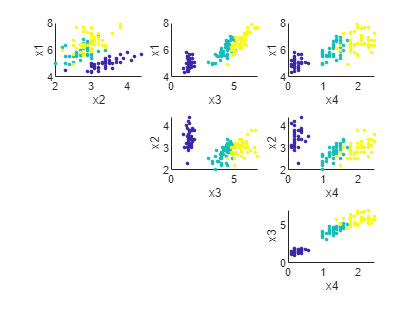

figure(1)                   % Graficamos cada variable del dataset con respecto a otra
for i=1:4
  for j=1:i-1
     subplot(3,3,(i-1)+3*(j-1))
     %scatter(X(i,:),X(j,:))
     scatter(X(i,:),X(j,:),7,spec,'filled')
     xlabel(sprintf('x%g',i)); ylabel(sprintf('x%g',j))
  end
end

Xmean = mean(X,2)           % Encontramos la media

Xmean =     5.8433
    3.0540
    3.7587
    1.1987


A = X - Xmean*ones(1,n); % Restamos la media
A=A'

A =    -0.7433    0.4460   -2.3587   -0.9987
   -0.9433   -0.0540   -2.3587   -0.9987
   -1.1433    0.1460   -2.4587   -0.9987
   -1.2433    0.0460   -2.2587   -0.9987
   -0.8433    0.5460   -2.3587   -0.9987
   -0.4433    0.8460   -2.0587   -0.7987
   -1.2433    0.3460   -2.3587   -0.8987
   -0.8433    0.3460   -2.2587   -0.9987
   -1.4433   -0.1540   -2.3587   -0.9987
   -0.9433    0.0460   -2.2587   -1.0987


C = cov(A)  %Calculamos la matriz de covarianzas

C =     0.6857   -0.0393    1.2737    0.5169
   -0.0393    0.1880   -0.3217   -0.1180
    1.2737   -0.3217    3.1132    1.2964
    0.5169   -0.1180    1.2964    0.5824


[V,D] = eig(C) %Ahora encontramos los autovalores y autovectores

V =    -0.3173    0.5810    0.6565    0.3616
    0.3241   -0.5964    0.7297   -0.0823
    0.4797   -0.0725   -0.1758    0.8566
   -0.7511   -0.5491   -0.0747    0.3588


D =     0.0237         0         0         0
         0    0.0785         0         0
         0         0    0.2422         0
         0         0         0    4.2248


diag(D) %Mostramos los autovalores

ans =     0.0237
    0.0785
    0.2422
    4.2248


newdata = V' * A'; %Transformamos los datos originales con la matriz de autovectores
newdata = newdata';
newdata = fliplr(newdata)

newdata =    -2.6842    0.3266    0.0215   -0.0010
   -2.7154   -0.1696    0.2035   -0.0996
   -2.8898   -0.1373   -0.0247   -0.0193
   -2.7464   -0.3111   -0.0377    0.0760
   -2.7286    0.3339   -0.0962    0.0631
   -2.2799    0.7478   -0.1743    0.0271
   -2.8209   -0.0821   -0.2643    0.0501
   -2.6265    0.1704    0.0158    0.0463
   -2.8880   -0.5708   -0.0273    0.0266
   -2.6738   -0.1067    0.1915    0.0559


var(newdata) %Encontramos las varianzas de los datos transformados

ans =     4.2248    0.2422    0.0785    0.0237


varianzas=var(newdata)/sum(var(newdata)) %Normalizamos las varianzas

varianzas =     0.9246    0.0530    0.0172    0.0052


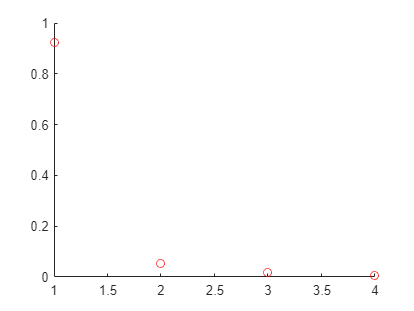

figure(2)
scatter([1,2,3,4],varianzas,"red") %Graficamos las varianzas normalizadas de cada una de las variables

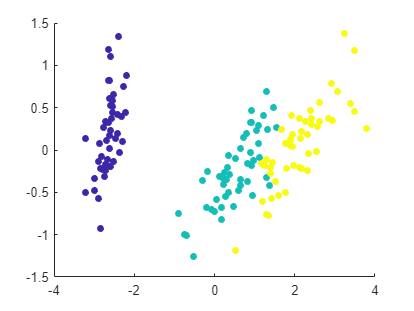

figure(3)
scatter(newdata(:,1),newdata(:,2),27,spec,'filled')

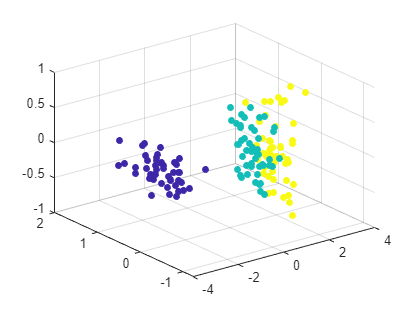

figure(4)
scatter3(newdata(:,1),newdata(:,2),newdata(:,3),27,spec,'filled') %Graficamos los datos después de una reducción a 3 dimensiones